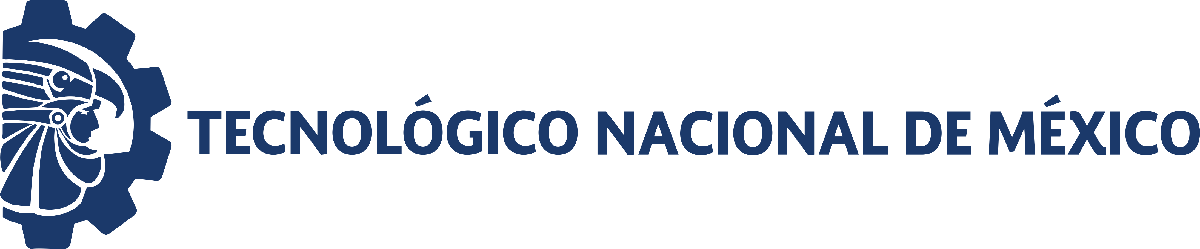                                 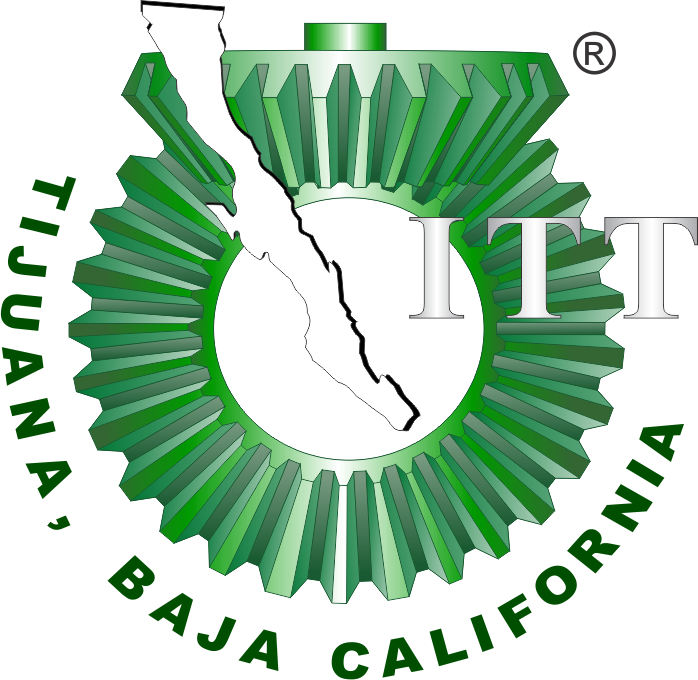

# Práctica 4: Regeneración de glóbulos rojos

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

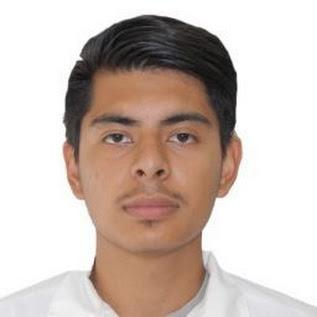

Nombre del alumno: Diego Saul Lopez Islas

Número de control: 22211759

Correo institucional: L22211759@tectijuana.edu.mx

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = 180;%tiempo de la simulacion end dias
dt = 1E-3; % intervalo de integracion para el metodo de solucion por diferencias finitas
n = round(tend/dt); %cantidad de iteraciones para el metodo numerico

%Condiciones iniciales base para cada paciente
x1_0 = 59;x2_0 = 44; x3_0 = 855;
%parametros particulares para cada paciente
gamma = [0.769; 0.388; 0.510; 0.590; 0.262; 0.324; 0.356; 0.089; 0.243; 0.057];
beta = [1.650; 0.867; 1.617; 2.615; 1.518; 2.676; 0.891; 2.557; 0.925; 0.879];

seed = 22211759; %Semilla para asegurar reproducibilidad
rng(seed,'twister')
%intervalo de las condiciones iniciales
xmin = 0.99; xmax = 1.01;
interval = xmin + (xmax-xmin).*rand(numel(gamma),1);

%condiciones iniciales para cada paciente
x1_0 = x1_0*interval;disp('x1(0) = ');disp(x1_0');...
x2_0 = x2_0*interval;disp('x2(0) = ');disp(x2_0');...
x3_0 = x3_0*interval;disp('x3(0) = ');disp(x3_0');...


x1(0) = 
   58.8003   59.2896   58.7754   59.1525   59.0111   58.5193   58.9471   58.7549   59.3771   58.4300



x2(0) = 
   43.8510   44.2160   43.8325   44.1138   44.0083   43.6415   43.9606   43.8172   44.2812   43.5749



x3(0) = 
  852.1056  859.1972  851.7447  857.2105  855.1611  848.0344  854.2337  851.4480  860.4641  846.7403



## **Caso: Sin transfusión sanguínea [u(t) =0]**

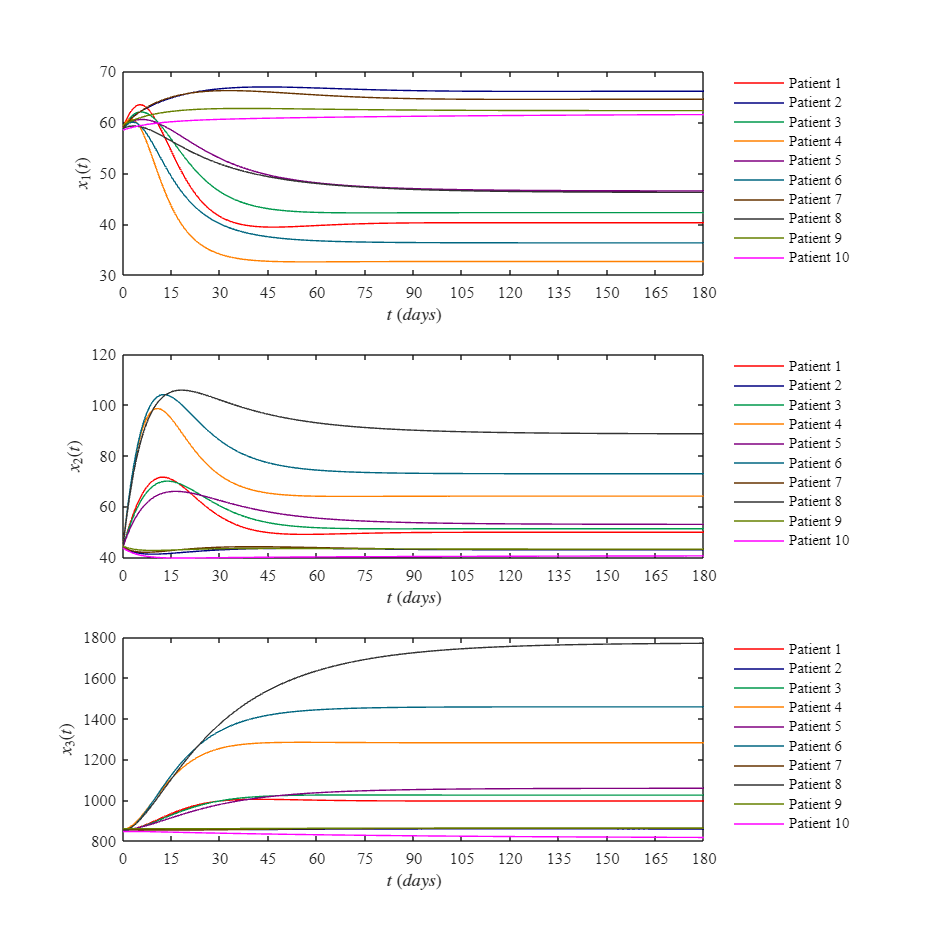

u = zeros(n+1,1); %no hay transfusion
fig = 1;
for i =1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## **Caso: Con transfusión sanguínea **              

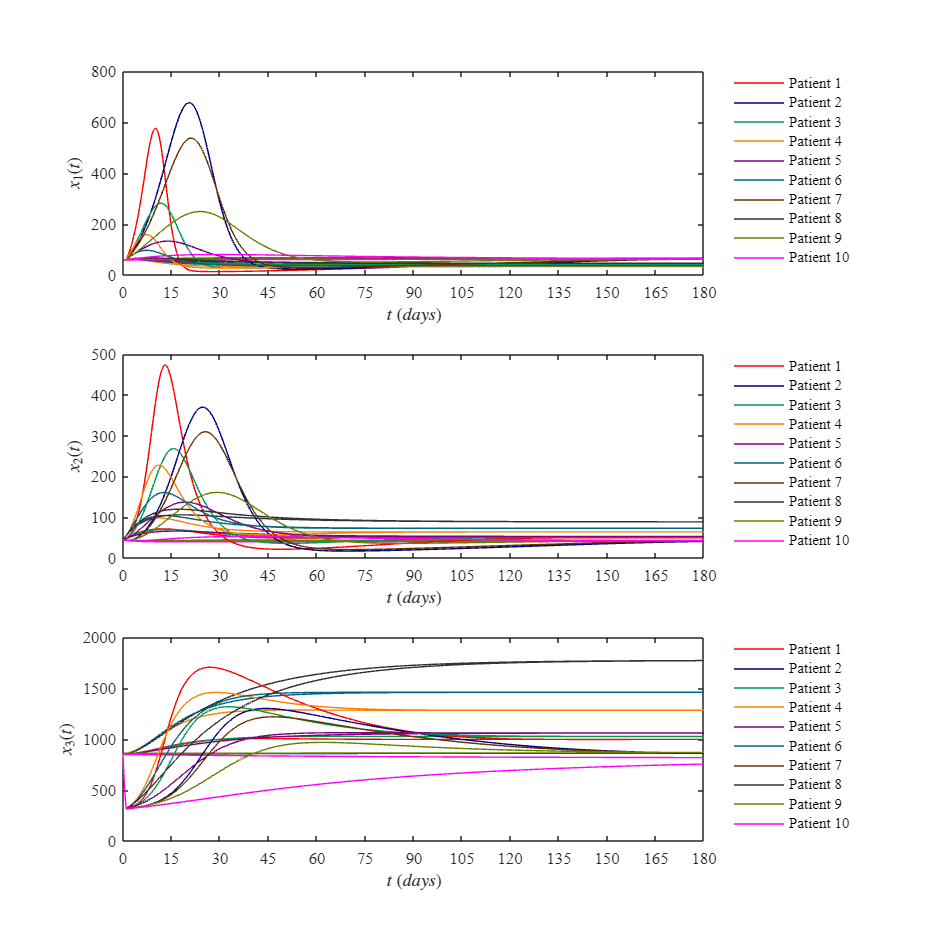

u = zeros(n+1,1); u(1 : round(1/dt)) = 1;    
fig = 2;
for i = 1:10
    [t, x1, x2, x3] = system(x1_0(i), x2_0(i), x3_0(i), beta(i), gamma(i), u, dt, tend);
    plotdata(t, x1, x2, x3, fig)
end

## Función: Modelo matemático


$${\overset{\ldotp }{x} }_1 =\beta \left(x_0 -k_1 x_1 \right)+\frac{\gamma \left(B_{\textrm{ase}} -x_3 \right)\left(1-u\left(t\right)\right)x_1 }{B_{\textrm{ase}} }$$



$${\overset{\ldotp }{x} }_2 =\beta \left(k_1 x_1 -k_2 x_2 \right)$$



$${\overset{\ldotp }{x} }_3 =\beta \left(k_2 x_2 -ax_3 \right)-u\left(t\right)x_3$$


function[t,x1,x2,x3] = system(x1_0,x2_0,x3_0,beta,gamma,u,dt,tend)
    Base = 885.42; X0 = 7.3785; k1 = 0.125; k2 = 0.1667; alpha = 0.00833;
    t = (0:dt:tend)';
    n = round (tend/dt);
    x1 = zeros(n+1,1);x1(1) = x1_0;
    x2 = zeros(n+1,1);x2(1) = x2_0;
    x3 = zeros(n+1,1);x3(1) = x3_0;
    for i = 1:n %metodo de euler(diferencias finitas)
        x1(i+1) = x1(i)+(beta*(X0 - k1*x1(i)) + gamma*(Base - x3(i))*(1 - u(i))*x1(i)/Base)*dt;
        x2(i+1) = x2(i) + (beta* k1*x1(i)- k2*x2(i))*dt;
        x3(i+1) = x3(i) + (beta*(k2*x2(i) - alpha*x3(i)) - u(i)*x3(i))*dt;

    end 
end

## Función: Soluciones en el tiempo

function plotdata(t,x1,x2,x3,fig)
    set(figure(fig),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,20,20])
        mycolor = [1.0, 0.0, 0.0;
                   0.0, 0.0, 0.5
                   0.0, 0.6, 0.3
                   1.0, 0.5, 0.0
                   0.5, 0.0, 0.5
                   0.0, 0.4, 0.5
                   0.4, 0.2, 0.0
                   0.2, 0.2, 0.2
                   0.4, 0.5, 0.0
                   1.0, 0.0, 1.0];
                   colororder(mycolor)

    subplot(3,1,1)
    hold on;grid off;box on;colororder(mycolor)
    plot(t,x1)
    xlabel('$t$ $(days)$','Interpreter','Latex','FontSize',10)
    ylabel('$x_1(t)$','Interpreter','Latex','FontSize',10)
    xlim([0,180]); xticks(0:15:180);
    L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
    'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'Fontname','Times New Roman','FontSize',10)
  
    subplot(3,1,2)
    hold on;grid off;box on;colororder(mycolor)
    plot(t,x2)
    xlabel('$t$ $(days)$','Interpreter','Latex','FontSize',10)
    ylabel('$x_2(t)$','Interpreter','Latex','FontSize',10)
    xlim([0,180]); xticks(0:15:180);
    L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
    'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'Fontname','Times New Roman','FontSize',10)

    subplot(3,1,3)
    hold on;grid off;box on;colororder(mycolor)
    plot(t,x3)
    xlabel('$t$ $(days)$','Interpreter','Latex','FontSize',10)
    ylabel('$x_3(t)$','Interpreter','Latex','FontSize',10)
    xlim([0,180]); xticks(0:15:180);
    L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
    'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'Fontname','Times New Roman','FontSize',10)

    if fig == 1
        exportgraphics(gcf,'Caso sin transfusión.pdf','ContentType','Vector')
    elseif fig == 2
        exportgraphics(gcf,'Caso Con transfusión.pdf','ContentType','Vector')
    end
end